# Step 1: Reaction Wheel

load('signal_3_12_5.mat');

## Load Data

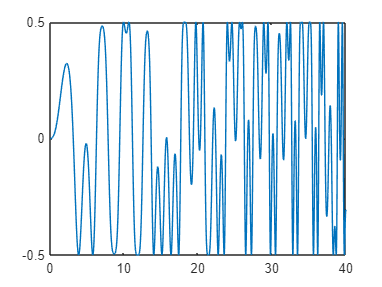

y = angular_velocity.data;
y = y(2:end);
N = size(t,2);
end_train = floor(N*1/2);
figure; 
plot(t,u)

clearvars -except y N t u

## Apply PEM

theta0 = [-5 1000 0.2]';
theta = theta0;
lambda = 0.1;
maxiter = 10000;
p = 3;
h = 0.01;

% initialize
converged = false;
maxiter_reached = false;
iter = 1;
while ~converged && ~maxiter_reached 

    [Abar,Bbar, C,x0] = theta2matrices_phi(theta, h);
    [yhat, xhat] = simsystem(Abar, Bbar, C, x0, u);
    E = y - yhat;
    psi = psi_fun_phi(xhat, x0, Abar, h, u);
    N_E = length(E);
    J = 2/N_E * psi' * E; % Jacobian
    N_H = size(psi,1);
    H = 2/N_H * (psi' * psi); % Hessian

    invLM = (H + lambda * eye(p))\eye(p); %Levenberg-Marquardt singularity inverse
    theta_new = theta - invLM * J;

    
    % Check convergence
    if norm(theta_new - theta) < 1e-6
        converged = true; 
    elseif iter == maxiter 
        maxiter_reached = true; 
        warning('Maximum iterations reached'); 
    end
    theta = theta_new; 
    iter = iter + 1;
end   


## Evaluate

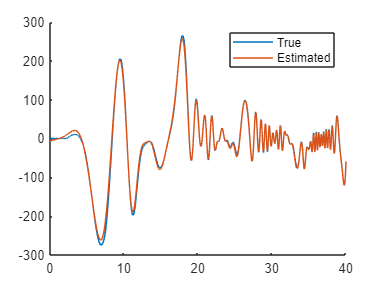

load('signal_3b_12_5.mat')
y = angular_velocity.data;
y = y(2:end);
[yhat, xhat] = simsystem(Abar, Bbar, C, x0, u);

figure;
hold on
plot(t,y);
plot(t,yhat);
legend('True', 'Estimated');


a1 = (1-Abar) / 0.01;
a5 = Bbar(1)/h;

# Part 2 : Pendulum

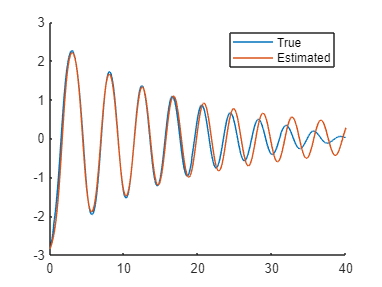

clearvars -except a1 a5
load('signal_2b_12_5.mat')
h = 0.01;
y = pendulum_angle.data;     % theta
y = y(2:end);
N = length(t);
u  = zeros(N,1);

% figure;
% plot(t,y);
% ylabel("\theta")
% title("Data 1")


data = iddata(y, u, 0.01);

FileName = 'theta_greybox';
Order = [1 1 2];      % 2 outputs, 1 input, 3 states

Parameters = {
    2.7;    % a3
    0.09;      % a4
    };

InitialStates = [y(1); (y(2)-y(1))/h];
Ts = 0;                % continuous-time model

sys = idnlgrey(FileName, Order, Parameters, InitialStates, Ts);

opt = nlgreyestOptions;
%opt.Display = 'on';

sys_est = nlgreyest(data, sys, opt);

a3 = sys_est.Parameters(1).Value;
a4 = sys_est.Parameters(2).Value;

load('signal_2_12_5.mat')
y = pendulum_angle.data;
y = y(2:end);
A = [1 h; -h*a3 1-h*a4];
C = [1 0];
x0 = [y(1); (y(2)-y(1))/h];
N = length(y);

[yhat,~] = simSystem_theta(A,C,x0,N);

figure;
hold on
plot(t,y);
plot(t,yhat);
legend('True', 'Estimated');

# Section 3 : The other bit

clearvars -except a1 a2 a3 a4 a5


load('signal_1b_12_5.mat')
y1 = angular_velocity.data;   % phi_dot
y2 = pendulum_angle.data;     % theta
N = length(t);

% Make sure input/output are column-based
y1 = y1(2:end);
y2 = y2(2:end);
u  = u(:);

data = iddata([y1 y2], u, 0.01);

FileName = 'inter_param_fun';
Order = [2 1 3];      % 2 outputs, 1 input, 3 states

Parameters = {
    a1
    -0.0074 % main decision var
    a3
    a4
    a5
    };

InitialStates = [0; 0; 0];
Ts = 0;                % continuous-time model

opt = nlgreyestOptions;
opt.Display = 'on';                 % optional, shows progress
opt.SearchOptions.MaxIterations = 50;

sys = idnlgrey(FileName, Order, Parameters, InitialStates, Ts);

sys.Parameters(1).Fixed = false;
sys.Parameters(2).Fixed = false;
sys.Parameters(3).Fixed = false;
sys.Parameters(4).Fixed = false;
sys.Parameters(5).Fixed = false;

sys_est = nlgreyest(data, sys, opt);

a2 = sys_est.Parameters(2).Value;
a3new = sys_est.Parameters(3).Value;
a4new = sys_est.Parameters(4).Value;

a1new = sys_est.Parameters(1).Value;
a5new = sys_est.Parameters(5).Value;

Validation (fuc off jack)(not ugly)

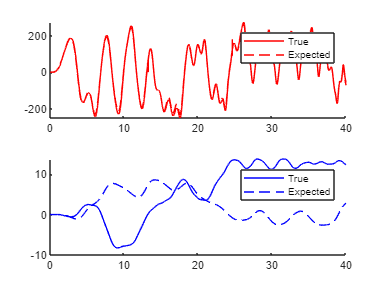

load('signal_1_12_5.mat')
y1 = angular_velocity.data;   % phi_dot
y2 = pendulum_angle.data;     % theta
N = length(t);
h = 0.01;

% Make sure input/output are column-based
y1 = y1(2:end);
y2 = y2(2:end);
u  = u(:);

x0 = [0; 0; 0];

A = [1-a1*h 0 0;
     0 1 h;
     a2*h -a3*h 1-a4*h];
B = [a5*h; 0; 0];
C = [1 0 0; 0 1 0];
D = [0; 0];

[yhat,~] = simSystem_sin(A,B,C,D,x0,u);
y1hat = zeros(N,1); y2hat = zeros(N,1);
for i = 1:N
    y1hat(i) = yhat((i-1)*2+1);
    y2hat(i) = yhat(i*2);
end

figure;
tiledlayout(2,1);
nexttile
hold on
plot(t,y1, 'color', 'red', 'LineStyle', '-');
plot(t,y1hat, 'color', 'red', 'LineStyle', '--');
legend('True', 'Expected')

nexttile
hold on
plot(t,y2, 'color', 'blue', 'LineStyle', '-');
plot(t,y2hat, 'color', 'blue', 'LineStyle', '--');
legend('True', 'Expected');

a1 = 1.0391;
a2 = -0.0093;
a3 = 2.6763;
a4 = 0.1070;
a5 = 420.45190;

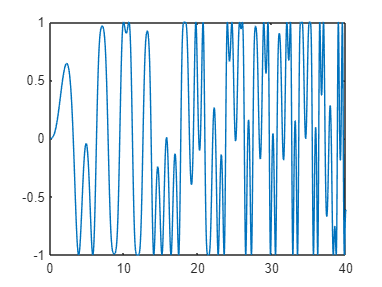

figure;
plot(t,u);

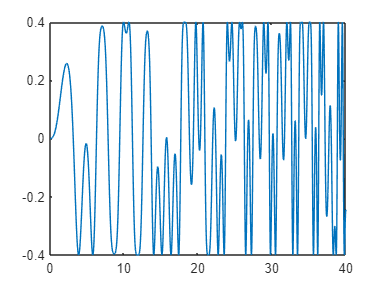

unew = 0.4*u;
figure;
plot(t,unew);

unew_ts = timeseries(unew', t)

  timeseries

  Common Properties:
            Name: 'unnamed'
            Time: [4000x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [4000x1 double]
        DataInfo: 

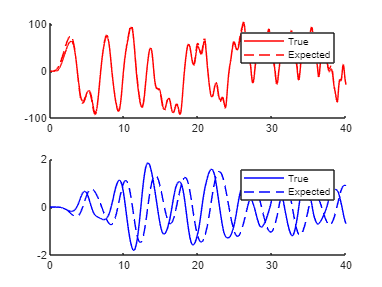

% Verification with new data
load("full_verification_05_18.mat")
y1 = angular_velocity.data;   % phi_dot
y2 = pendulum_angle.data;     % theta
N = length(t);
h = 0.01;

% Make sure input/output are column-based
y1 = y1(2:end);
y2 = y2(2:end);
u  = u(:);

x0 = [0; 0; 0];

A = [1-a1*h 0 0;
     0 1 h;
     a2*h -a3*h 1-a4*h];
B = [a5*h; 0; 0];
C = [1 0 0; 0 1 0];
D = [0; 0];

[yhat,~] = simSystem_sin(A,B,C,D,x0,unew);
y1hat = zeros(N,1); y2hat = zeros(N,1);
for i = 1:N
    y1hat(i) = yhat((i-1)*2+1);
    y2hat(i) = yhat(i*2);
end

figure;
tiledlayout(2,1);
nexttile
hold on
plot(t,y1, 'color', 'red', 'LineStyle', '-');
plot(t,y1hat, 'color', 'red', 'LineStyle', '--');
legend('True', 'Expected')

nexttile
hold on
plot(t,y2, 'color', 'blue', 'LineStyle', '-');
plot(t,y2hat, 'color', 'blue', 'LineStyle', '--');
legend('True', 'Expected');